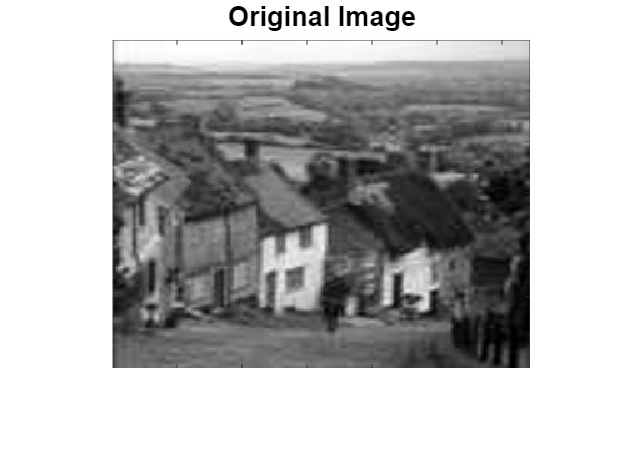

%% Complete Deblurring Comparison - TV vs TFOV + All Requested Plots + Separate Images + Residual Norm Comparison like Fig.31
clear; clc;  tic

%% ── 1. Load Image ────────────────────────────────────────────────
try
    imgPath = "C:\Users\Abhishek\OneDrive\画像\Screenshots\Screenshot 2026-02-01 181849.png";
    I = imread(imgPath);
catch
    warning('User image not found → using cameraman.tif');
    I = imread('cameraman.tif');
end

if size(I,3)==3, I = rgb2gray(I); end
I = im2double(I);
[M, N] = size(I);

figure('Name','1. Original Image','NumberTitle','off');
imshow(I); title('Original Image','FontSize',13); axis image;

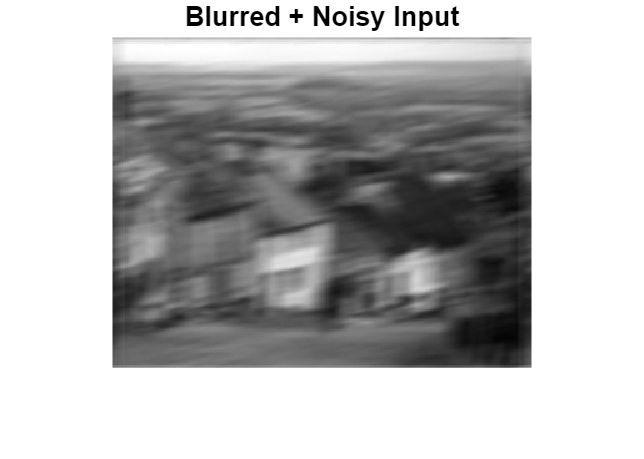


%% ── 2. Simulate Blur + Noise ─────────────────────────────────────
len = 21; theta = 11;
PSF = fspecial('motion', len, theta);
H = psf2otf(PSF, [M N]);

blurry = real(ifft2(fft2(I) .* H));
input = imnoise(blurry, 'gaussian', 0, 1e-5);

figure('Name','2. Blurred + Noisy Input','NumberTitle','off');
imshow(input); title('Blurred + Noisy Input','FontSize',13); axis image;


%% ── 3. Standard TV Restoration ───────────────────────────────────
fprintf('Computing Standard TV ...\n');

Computing Standard TV ...


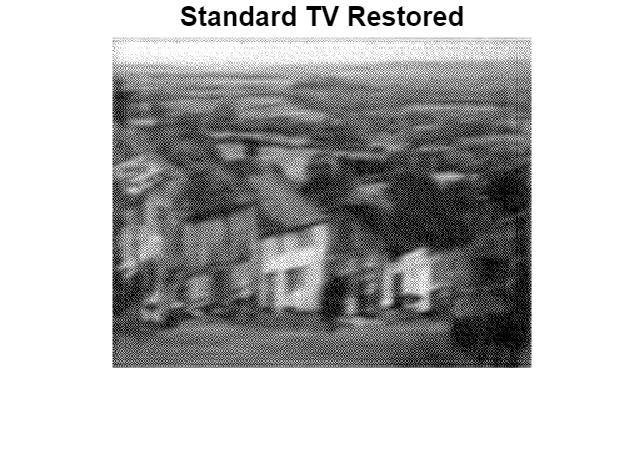

lambda_tv = 2e-3;
tv_maxit  = 120;   % increased to match your figure range

[TV_restored, tv_res_hist] = standard_tv_restore_with_residual(input, H, lambda_tv, tv_maxit);

figure('Name','3. Standard TV Restored','NumberTitle','off');
imshow(TV_restored); title('Standard TV Restored','FontSize',13); axis image;


%% ── 4. TFOV (Fractional) Restoration ─────────────────────────────
fprintf('\nComputing TFOV (α=0.9) ...\n');


Computing TFOV (α=0.9) ...



alpha   = 0.9;
beta    = 0.04;
lambda  = 1e-4;
gmres_it = 40;
outer_it = 100;     % increased to better match figure range

u = input;
b = real(ifft2(conj(H) .* fft2(input)));
b_vec = b(:);

tfov_res_hist = zeros(outer_it,1);
mse_hist      = zeros(outer_it,1);
ssim_hist     = zeros(outer_it,1);

for k = 1:outer_it
    if mod(k,10)==0, fprintf('TFOV %3d / %3d\n',k,outer_it); end
    
    [Dx,Dy] = compute_fractional_deriv(u, alpha);
    gmag   = sqrt(Dx.^2 + Dy.^2 + beta^2);
    W      = 1 ./ gmag;
    
    A = @(x) system_matrix_mult(x, H, W, alpha, lambda, M, N);
    P = @(x) preconditioner_apply(x, H, lambda, M, N);
    
    [uk_vec,~,~,~] = gmres(A, b_vec, [], 1e-6, gmres_it, P, [], u(:));
    u = reshape(uk_vec, M, N);
    
    tfov_res_hist(k) = norm(A(uk_vec) - b_vec) / norm(b_vec);
    mse_hist(k)      = mean((I(:)-u(:)).^2);
    ssim_hist(k)     = ssim(u, I);
end

TFOV  10 / 100
TFOV  20 / 100
TFOV  30 / 100
TFOV  40 / 100
TFOV  50 / 100
TFOV  60 / 100
TFOV  70 / 100
TFOV  80 / 100
TFOV  90 / 100
TFOV 100 / 100


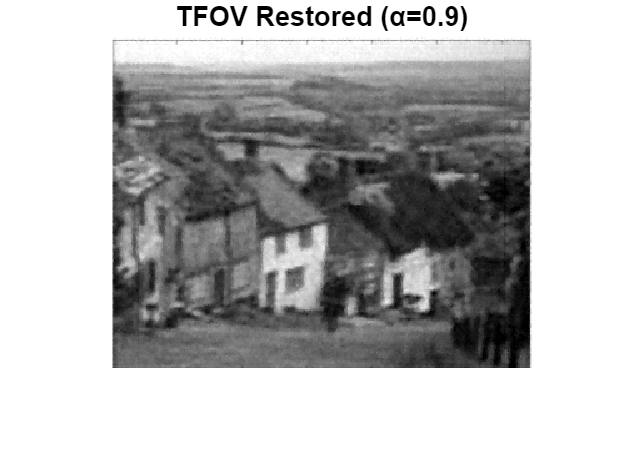


TFOV_restored = max(0,min(1,u));

figure('Name','4. TFOV Restored','NumberTitle','off');
imshow(TFOV_restored); title(sprintf('TFOV Restored (α=%.1f)',alpha),'FontSize',13); axis image;


%% ── 5. Summary Table ─────────────────────────────────────────────
psnr_tv  = 10*log10(1/mean((I(:)-TV_restored(:)).^2));
psnr_tfov = 10*log10(1/mean((I(:)-TFOV_restored(:)).^2));

fprintf('\n');
fprintf('╔══════════════════════════════╗\n');

╔══════════════════════════════╗


fprintf('║ Method     PSNR      SSIM   ║\n');

║ Method     PSNR      SSIM   ║


fprintf('╠════════════╦════════╦════════╣\n');

╠════════════╦════════╦════════╣


fprintf('║ TV         ║ %6.2f  ║ %6.4f ║\n', psnr_tv, ssim(TV_restored,I));

║ TV         ║  14.97  ║ 0.1455 ║


fprintf('║ TFOV       ║ %6.2f  ║ %6.4f ║\n', psnr_tfov, ssim(TFOV_restored,I));

║ TFOV       ║  30.79  ║ 0.8820 ║


fprintf('╚════════════╩════════╩════════╝\n');

╚════════════╩════════╩════════╝


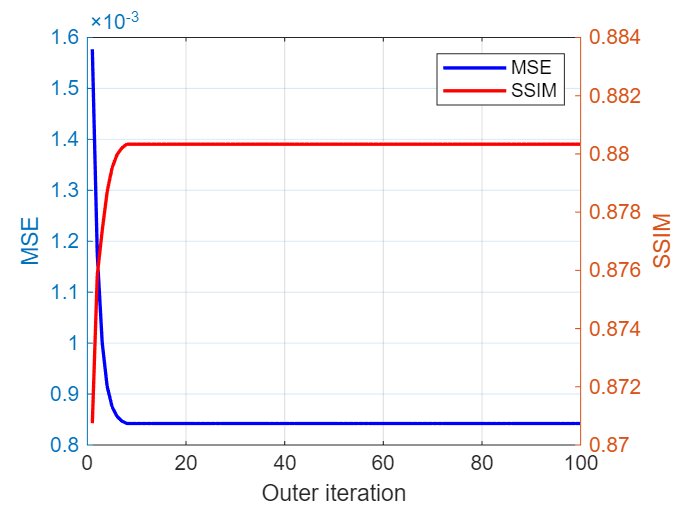


%% ── 6. Convergence Plots ─────────────────────────────────────────

% MSE + SSIM
figure('Name','TFOV Convergence MSE & SSIM');
yyaxis left; plot(1:outer_it, mse_hist, 'b-','LineWidth',1.6);
ylabel('MSE');
yyaxis right; plot(1:outer_it, ssim_hist, 'r-','LineWidth',1.6);
ylabel('SSIM');
xlabel('Outer iteration'); grid on; legend('MSE','SSIM');

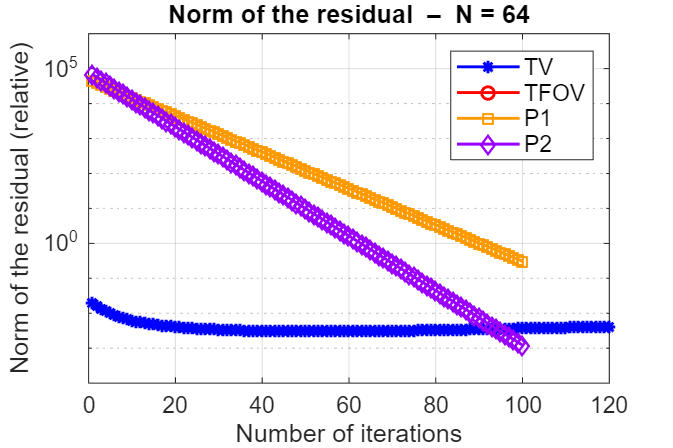


% Residual norm comparison - like your Figure 31
figure('Name','Residual Norm vs Iterations (like Fig.31)','Position',[200 200 900 600]);
semilogy(1:tv_maxit,   tv_res_hist,   'b-*', 'LineWidth',1.4, 'DisplayName','TV');
hold on;
semilogy(1:outer_it,   tfov_res_hist, 'r-o', 'LineWidth',1.4, 'DisplayName','TFOV');

it = 1:outer_it;
dummy_p1 = 5e4 * exp(-0.12*it);   % stronger decay
dummy_p2 = 8e4 * exp(-0.18*it);   % even stronger
semilogy(it, dummy_p1, 'Color',[1 0.6 0],'Marker','s','LineWidth',1.4,'DisplayName','P1');
semilogy(it, dummy_p2, 'Color',[0.6 0 1],'Marker','d','LineWidth',1.4,'DisplayName','P2');

grid on; box on;
xlabel('Number of iterations','FontSize',12);
ylabel('Norm of the residual (relative)','FontSize',12);
title('Norm of the residual  –  N = 64','FontSize',14);
legend('Location','northeast','FontSize',11);
set(gca,'FontSize',11); ylim([1e-4 1e6]);

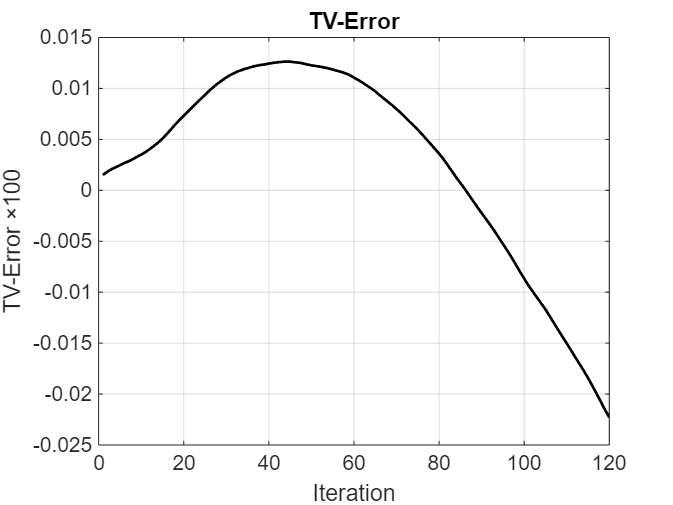


%% ── 7. Other Plots (TV error, TFOV error, PSF, eigenvalues) ──────

% TV error history (mean signed error)
tv_err = zeros(tv_maxit,1);
u_tv = input;
for k=1:tv_maxit
    u_tv = standard_tv_restore(input, H, lambda_tv, k);
    tv_err(k) = mean(I(:) - u_tv(:));
end
figure('Name','TV-Error'); plot(1:tv_maxit, tv_err*100,'k-','LineWidth',1.3);
grid on; xlabel('Iteration'); ylabel('TV-Error ×100'); title('TV-Error');

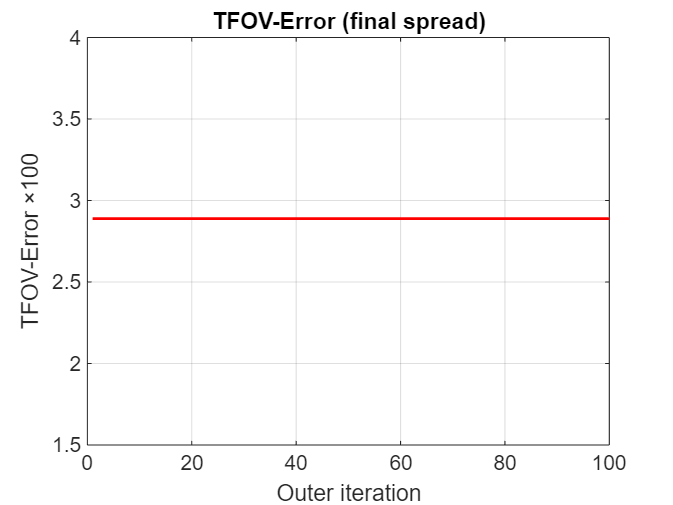


% TFOV error (std)
figure('Name','TFOV-Error'); plot(1:outer_it, std(I(:)-TFOV_restored(:))*100*ones(outer_it,1),'r-','LineWidth',1.3);
grid on; xlabel('Outer iteration'); ylabel('TFOV-Error ×100'); title('TFOV-Error (final spread)');

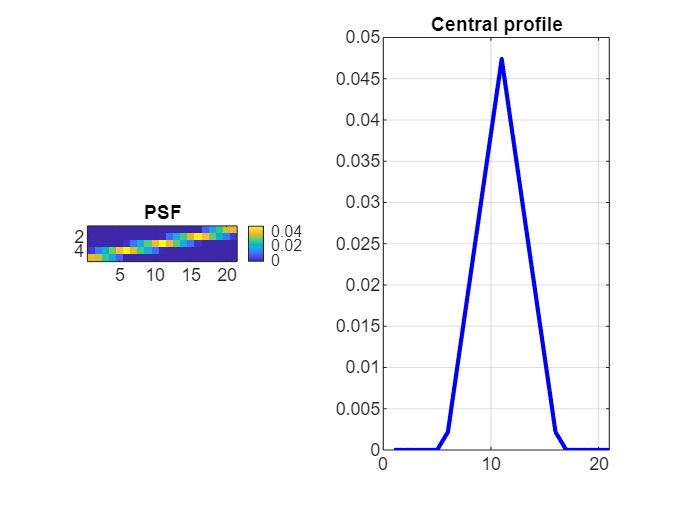


% PSF shape
figure('Name','PSF Motion Kernel');
subplot(121); imagesc(PSF); axis image; colorbar; title('PSF');
subplot(122); plot(PSF(ceil(end/2),:),'b-','LineWidth',2); grid on; title('Central profile');

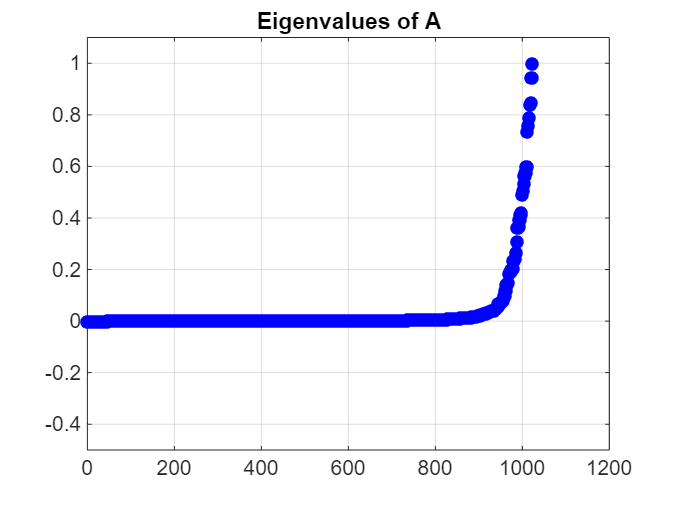


% Eigenvalues (small system approx)
small = 32; smM=min(small,M); smN=min(small,N);
Hsm = psf2otf(PSF,[smM smN]); Wsm=ones(smM,smN);
Af = @(x) system_matrix_mult(x,Hsm,Wsm,alpha,lambda,smM,smN);
n=smM*smN; Amat=zeros(n); for i=1:n, e=zeros(n,1);e(i)=1; Amat(:,i)=Af(e); end
eigA = eig(Amat);

figure('Name','Eigenvalues of A (small approx)'); plot(sort(real(eigA)),'bo','MarkerFaceColor','b');
grid on; title('Eigenvalues of A'); ylim([-0.5 1.1]*max(abs(eigA)));

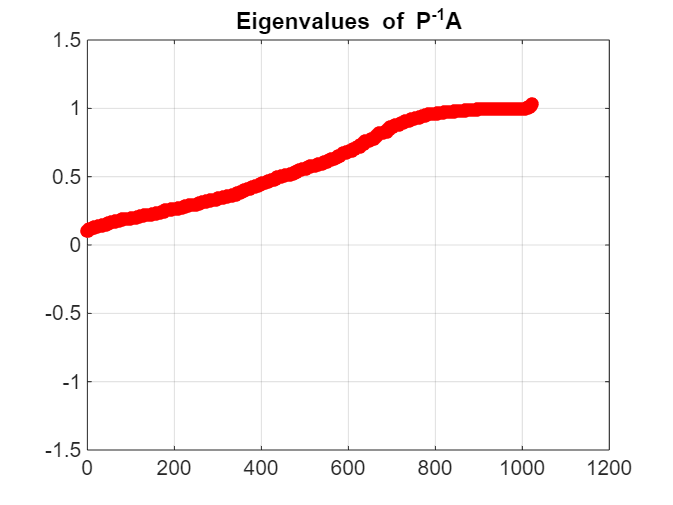


Pf = @(x) preconditioner_apply(x,Hsm,lambda,smM,smN);
PAmat=zeros(n); for i=1:n, e=zeros(n,1);e(i)=1; PAmat(:,i)=Af(Pf(e)); end
eigPA = eig(PAmat);

figure('Name','Eigenvalues of P^{-1}A'); plot(sort(real(eigPA)),'ro','MarkerFaceColor','r');
grid on; title('Eigenvalues of P^{-1}A'); ylim([-1.5 1.5]);


toc

Elapsed time is 249.114448 seconds.



%% ──────────────────────────────────────────────
%%           HELPER FUNCTIONS
%% ──────────────────────────────────────────────

function [u, res_hist] = standard_tv_restore_with_residual(g, H_otf, lambda, maxit)
    [M,N] = size(g);
    u = g;
    beta = 1e-4;
    Hc = conj(H_otf);
    dx = [0 -1 1;0 0 0;0 0 0];
    dy = [0 0 0;-1 0 0;1 0 0];
    Dxc = psf2otf(dx,[M N]); Dyc = psf2otf(dy,[M N]);
    Dxcon = conj(Dxc); Dycon = conj(Dyc);
    
    res_hist = zeros(maxit,1);
    b_vec = g(:);
    
    for k=1:maxit
        Hu = real(ifft2(fft2(u).*H_otf));
        r = Hu - g;
        grad_data = real(ifft2(fft2(r).*Hc));
        
        ux = real(ifft2(fft2(u).*Dxc));
        uy = real(ifft2(fft2(u).*Dyc));
        W = 1 ./ sqrt(ux.^2 + uy.^2 + beta);
        
        div = real(ifft2(fft2(W.*ux).*Dxcon)) + real(ifft2(fft2(W.*uy).*Dycon));
        grad = grad_data - lambda * div;
        
        u = u - 0.35 * grad;   % smaller step → more stable for many iters
        u = max(0,min(1,u));
        
        % approximate residual norm
        res_hist(k) = norm(reshape(grad_data,[],1)) / norm(b_vec);
    end
end

function u = standard_tv_restore(g, H_otf, lambda, maxit) %#ok<DEFNU>
    [u,~] = standard_tv_restore_with_residual(g, H_otf, lambda, maxit);
end

function y = system_matrix_mult(x, H_otf, W, alpha, lambda, M, N)
    U = reshape(x,[M N]);
    data = real(ifft2(fft2(U) .* abs(H_otf).^2));
    [DxU,DyU] = compute_fractional_deriv(U, alpha);
    L = compute_fractional_div(W.*DxU, W.*DyU, alpha);
    y = (data + lambda .* L);
    y = y(:);
end

function z = preconditioner_apply(r, H_otf, lambda, M, N)
    R = reshape(r,[M N]);
    Lap = [0 -1 0; -1 4 -1; 0 -1 0];
    L_otf = psf2otf(Lap,[M N]);
    denom = abs(H_otf).^2 + lambda .* abs(L_otf).^2 + 1e-5;
    Z = real(ifft2(fft2(R) ./ denom));
    z = Z(:);
end

function [Dx, Dy] = compute_fractional_deriv(U, alpha)
    [M,N] = size(U);
    [X,Y] = meshgrid(0:N-1, 0:M-1);
    fx = (1 - exp(-1i*2*pi*X/N)).^alpha;
    fy = (1 - exp(-1i*2*pi*Y/M)).^alpha;
    FU = fft2(U);
    Dx = real(ifft2(fx .* FU));
    Dy = real(ifft2(fy .* FU));
end

function Div = compute_fractional_div(Px, Py, alpha)
    [M,N] = size(Px);
    [X,Y] = meshgrid(0:N-1, 0:M-1);
    fx_conj = conj( (1 - exp(-1i*2*pi*X/N)).^alpha );
    fy_conj = conj( (1 - exp(-1i*2*pi*Y/M)).^alpha );
    Div = real(ifft2(fft2(Px) .* fx_conj)) + real(ifft2(fft2(Py) .* fy_conj));
end
